clear
map3D = occupancyMap3D(4)

map3D =   occupancyMap3D with properties:

    ProbabilitySaturation: [1.0000e-03 0.9990]
               Resolution: 4
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000


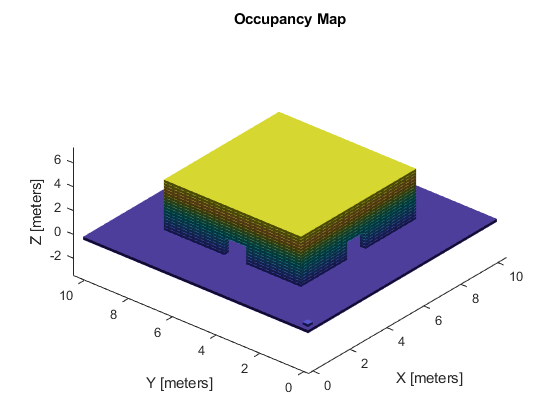

hMap =   Axes (Occupancy Map) with properties:

             XLim: [-0.2500 10.5000]
             YLim: [-0.2500 10.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties




pose = [ 0 0 0 1 0 0 0];

n=1;
for i=0:0.25:10
    for j=0:0.25:10
        Piso(n,:)=[j,i,-0.4];
        n=n+1;
    end
end

n=1;
for i=2:0.25:(8-0.25)
    for k=0:0.25:4
        
        if(i>=4.5&&i<5.5&&k>=0&&k<1.5)
            continue
        end
        
        ParedX1(n,:)=[i,2,k];
        n=n+1;
    end
end

n=1;
for i=2:0.25:(8-0.25)
    for k=0:0.25:4
        if(i>=4.5&&i<5.5&&k>=0&&k<1.5)
            continue
        end
        ParedX2(n,:)=[i,8,k];
        n=n+1;
    end
end

n=1;
for j=2:0.25:(8-0.25)
    for k=0:0.25:4
        if(j>=4.5&&j<5.5&&k>=0&&k<1.5)
            continue
        end
        ParedY1(n,:)=[2,j,k];
        n=n+1;
    end
end

n=1;
for j=2:0.25:(8)
    for k=0:0.25:4
        if(j>=4.5&&j<5.5&&k>=0&&k<1.5)
            continue
        end
        ParedY2(n,:)=[8,j,k];
        n=n+1;
    end
end


for i=2:0.25:(8-0.25)
    for j=2:0.25:(8-0.25)
        
        if(i>=2.5&&i<3.5&&j>=4.5&&j<5.5)
            %agujero 1
            continue
        end
        
        if(j>=2.5&&j<3.5&&i>=4.5&&i<5.5)
            %agujero 2
            continue
        end
        
        if(i>=6.5&&i<7.5&&j>=4.5&&j<5.5)
            %agujero 3
            continue
        end
        if(j>=6.5&&j<7.5&&i>=4.5&&i<5.5)
            %agujero 4
            continue
        end
        
        
        Techo(n,:)=[i,j,2];
        n=n+1;
    end
end


for i=2:0.25:(8-0.25)
    for j=2:0.25:(8-0.25)
        Techo2(n,:)=[i,j,4];
        n=n+1;
    end
end


maxRange = 15;
Puntos=[Piso;Techo2;Techo;ParedX1;ParedX2;ParedY1;ParedY2];
%Puntos=[Piso;Techo]
insertPointCloud(map3D,pose,Puntos,maxRange)
%inflate(map3D,0.25)
hMap = show(map3D)



doc h

doc insertPointCloud